# Automation of Liquid Level Control

The objective of this case study is to automatically maintain a liquid level in the lower of two dual gravity drained tanks.

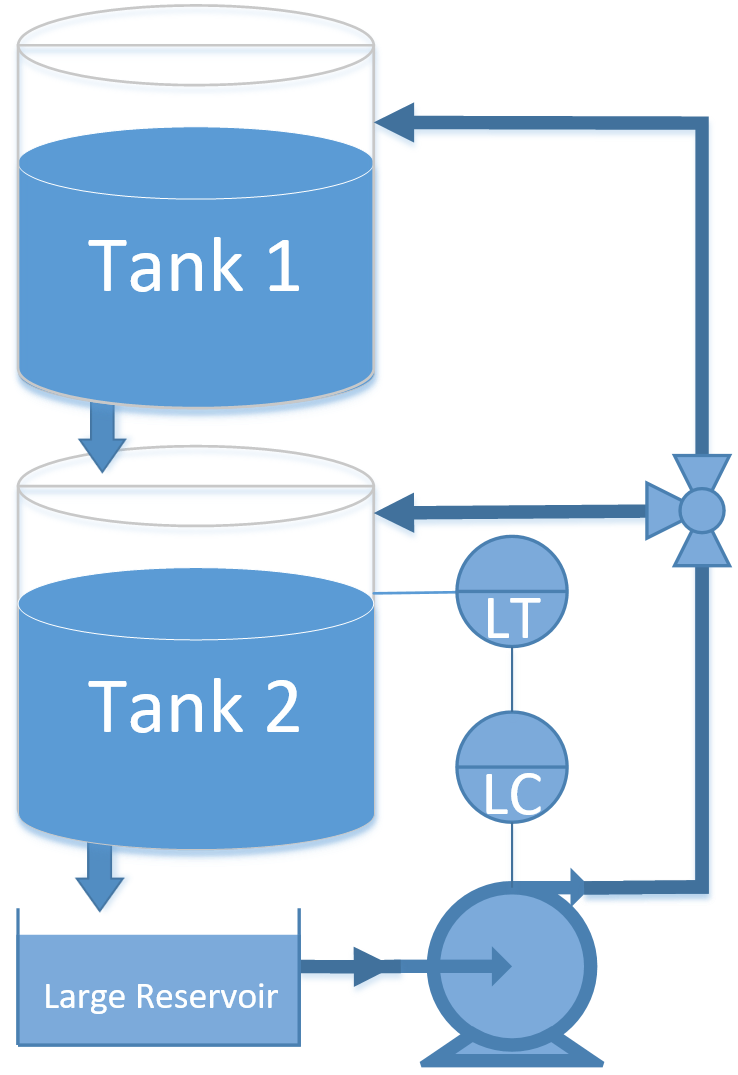

The exercise involves creating a dynamic first-order model, obtaining tuning parameters, and adjusting the PID tuning to achieve acceptable performance.

## Step Test with Graphical FOPDT Fit

For the gravity drained tank problem, conduct a step test by manipulating the pump rate and recording the level in the bottom tank. Use graphical methods to obtain a FOPDT model and report the values of the three parameters $(K_p,\tau_p,\theta_p)$

### Input Parameters & Initial Conditions

h0 = [0 0];
tf = 200;
ts = linspace(0,tf,tf+1);
% Inputs that can be adjusted
pump = zeros(tf+1,1);
% Pump operates between 0 and 1
pump(10:end) = 0.2;
% valve = 0, directly into top tank
% valve = 1, directly into bottom tank
valve = 0;
% Record the solution
h = zeros(tf+1,2);
h(1,:) = h0;

### Simulate Tank Step Test

for i = 1:tf
    % Specify the pump and valve
    inputs = [pump(i) valve];
    % Integrate the model
    [t,y] = ode45(@(t,y) tank(t,y,pump(i),valve), [0 1], h0);
    % Record the result
    h(i+1,:) = y(end,:);
    % Reset the intial condition
    h0 = y(end,:);
end

### Plot the results

subplot(2,1,1)
plot(ts,h(:,1),'b-','LineWidth',3); hold on
plot(ts,h(:,2),'r--','LineWidth',3); hold off
ylabel('Height (m)');
legend({'Height 1', 'Height2'});
title('Simulated Step Test')

subplot(2,1,2)
plot(ts,pump,'k-','LineWidth',3);
legend({'Pump'});
ylabel('Pump');
xlabel('Time (sec)');

## Fit FOPDT with Optimization

viewSolution(false)

Use optimization to obtain the same parameters in the FOPDT model. **The functions fopdt, sim_model, and objective will be useful.** Compare the optimized values with those obtained graphically. Are they the same? Why or why not? Which values would you use and why?

## Repeat with Doublet Test

viewSolution2(false)

Repeat the test using a doublet test instead of a step test. Fit FOPDT parameters using optimization of the three parameters $(K_p,\tau_p,\theta_p)$. Why is it important to obtain values above and below the steady state value for nonlinear processes?

## Design and Tune PI Controller

viewSolution3(false)

Use an appropriate tuning rule (either ITAE or IMC) to obtain a starting value for the controller gain ($K_C$) and integral reset time $(\tau_I)$ of a [**PI controller**](https://apmonitor.com/pdc/index.php/Main/ProportionalIntegralControl). Implement the PI controller (with anti-reset windup) and tune the controller constants (adjust up or down) until an acceptable response is achieved for step changes in the set point. Include plots of with initial values, tuned values, and a justification of your criteria for an acceptable response. Remember to define your criteria in terms of rise time, peak time, overshoot ratio, damping ratio and settling time.

## Functions

### Model the Tank Behavior

function dhdt = tank(~,levels,pump,valve)
    h1 = max(0,levels(1));
    h2 = max(0,levels(2));
    c1 = 0.08; % inlet valve coefficient
    c2 = 0.04; % tank outlet coefficient
    dhdt1 = c1*(1-valve)*pump - c2*sqrt(h1);
    dhdt2 = c1*valve*pump + c2*sqrt(h1)-c2*sqrt(h2);
    % overflow conditions
    if h1 >= 1.0 && dhdt1 > 0
        dhdt1 = 0;
    end
    if h2 >= 1.0 && dhdt2 > 0
        dhdt2 = 0;
    end
    dhdt = [dhdt1 dhdt2];
    dhdt = reshape(dhdt, [], 1);
end

### FOPDT Model

function dydt = fopdt(t,y,ts,pump,Km,tau_m,theta_m)
    % arguments
    %  t      = time
    %  y      = output
    %  ts     = the time steps for the pump output
    %  pump   = the pump output
    %  uf     = input linear function (for time shift)
    %  Km     = model gain
    %  tau_m   = model time constant
    %  theta_m = model time constant
    
    % time-shift u
    if (t - theta_m) <= 0
        um = interp1(ts,pump,0);
    else
        um = interp1(ts,pump,t-theta_m);
    end
    dydt = (-y + Km*um)/tau_m;
end

### Simulated Model

function ym = sim_model(ts,pump,Km,tau_m,theta_m,tf,dt)
    % input arguments
    %  ts      = the time steps for the pump output
    %  pump    = the pump output
    %  Km      = model gain
    %  tau_m   = model time constant
    %  theta_m = model time constant
    %  tf      = number of time points
    %  dt      = the size of a time step
    
    % storage for model values
    ym = zeros(tf+1,1);
    ym(1) = 0;
    for i = 2:(tf+1)
        t_span = [dt*(i-2) dt*(i-1)];
        [~,y] = ode45(@(t,y) fopdt(t,y,ts,pump,Km,tau_m,theta_m), t_span, ym(i-1));
        ym(i) = y(end);
    end
end

### Objective Function for Optimization

function obj = objective(x,xVals,yVals,tf,yp,dt)
    % Get parameters
    Km = x(1);
    tau_m = x(2);
    theta_m = x(3);
    % Run simulation
    ym = sim_model(xVals,yVals,Km,tau_m,theta_m,tf,dt);
    % Calculate objective
    obj = 0.0;
    for i = 1:length(ym)
        obj = obj + (ym(i)-yp(i))^2;
    end
end

### PID Controller

function [pv, co, e] = PID(ubias, Kc, Ki, Kd, bounds, ts, sp, pv0, model)
    n = length(sp);
    e = zeros(n,1);
    pv = zeros([n,1,2]);
    co = zeros(n,1);
    co(1) = ubias;
    pv(1,:) = pv0;
    integral = 0.0;
    dt = ts(2)-ts(1);
    for i = 1:n-1
        % Get error
        e(i) = sp(i) - pv(i,end);
        % Integral of error
        integral = integral + e(i)*dt;
        % Derivative on PV (not error)
        if i >= 2
            deriv = (pv(i) - pv(i-1))/dt;
        else
            deriv = 0;
        end
        % Get new controller output
        co(i) = co(1) + Kc*e(i) + Ki*integral - Kd*deriv;
        % Clip bounds of pump
        if co(i) > bounds(2)
            integral = integral - e(i)*dt;
            co(i) = bounds(2);
        elseif co(i) < bounds(1)
            integral = integral - e(i)*dt;
            co(i) = bounds(1);
        end
        % Integrate the model
        [~,y] = ode45(@(t,y) model(t,y,co(i)), [ts(i) ts(i)+dt], pv(i,:));
        % Record the result
        pv(i+1,:) = y(end,:);
    end
end

function [op,P,I,D] = PID_tuning(Kc,tauI,tauD,sp,pv,pv_last,ierr,dt)
%     INPUTS
%     sp - set point
%     pv - current process value
%     pv_last - previous process value
%     ierr - integral error
%     dt - time incriment between measurements
%     OUTPUTS
%     op - output of controller
%     P - porportional contribution
%     I - integral contribution
%     D - derivative contribution
    KP = Kc;
    KI = Kc/tauI;
    KD = Kc*tauD;
    % ubias for controller (initial heater)
    op0 = 0;
    % upper and lower bounds on heater level
    ophi = 1.0;
    oplo = 0.0;
    % calculate the error
    error = sp-pv;
    % calculate the integral error
    ierr = ierr +   error * dt;
    % calculate the measurement derivative
    dpv = (pv - pv_last) / dt;
    % calculate the PID output
    P = KP * error;
    I = ierr * KI;
    D = -KD * dpv;
    op = op0 + P + I + D;
    % implement anti-reset windup
    if op < oplo || op > ophi
        I = I - KI * error * dt;
        % clip output
        op = max(oplo,min(ophi,op));
    end
end

## Solutions

function viewSolution(view)
if view
	disp("yp = h(:,2);" + newline + ...
	     "yp0 = yp(1);" + newline + ...
	     "dt = ts(2) - ts(1);" + newline + ...
	     "dy = h(2,end);" + newline + ...
	     "du = 0.2;" + newline + ...
	     "Km = dy/du;" + newline + ...
	     "taum = 30; % sec" + newline + ...
	     "thetam = 2; % sec" + newline + ...
	     "x0 = [0.75 40 0];" + newline + ...
	     "" + newline + ...
	     "sol = fminsearch(@(x) objective(x, ts, pump, tf, yp, dt),x0);" + newline + ...
	     "" + newline + ...
	     "Kp_op = sol(1)" + newline + ...
	     "tau_op = sol(2)" + newline + ...
	     "theta_op = sol(3)" + newline + ...
	     "" + newline + ...
	     "initial = sim_model(ts, pump, 0.75, 40, 0, tf, dt);" + newline + ...
	     "opt = sim_model(ts, pump, Kp_op, tau_op, theta_op, tf, dt);" + newline + ...
	     "" + newline + ...
	     "subplot(2,1,1)" + newline + ...
	     "plot(ts,opt,'b-','LineWidth',3); hold on" + newline + ...
	     "plot(ts,initial,'y-','LineWidth',3);" + newline + ...
	     "plot(ts,h(:,2),'r--','LineWidth',3); hold off" + newline + ...
	     "ylabel('Height (m)');" + newline + ...
	     "legend({'Optimized fit','Initial fit','Process Data'});" + newline + ...
	     "title('Graphical vs. Optimized FOPDT Fit')" + newline + ...
	     "" + newline + ...
	     "subplot(2,1,2)" + newline + ...
	     "plot(ts,pump,'k-','LineWidth',3);" + newline + ...
	     "legend({'Pump'});" + newline + ...
	     "xlabel('Pump')" + newline + ...
	 "end")
end
end

function viewSolution2(view)
if view
	disp("sp = zeros(tf+1,1);" + newline + ...
	     "sp(10:end) = 0.1;" + newline + ...
	     "sp(50:end) = 0.4;" + newline + ...
	     "sp(100:end) = 0.2;" + newline + ...
	     "sp(150:end) = 0.6;" + newline + ...
	     "" + newline + ...
	     "% create PID controller" + newline + ...
	     "% op = op_bias + Kc * e + Ki * ei + Kd * ed" + newline + ...
	     "%      with ei = error integral" + newline + ...
	     "%      with ed = error derivative" + newline + ...
	     "Kc = 2.0;   % Controller gain" + newline + ...
	     "Ki = 0.03;  % Controller integral parameter" + newline + ...
	     "Kd = 0.0;   % Controller derivative parameter" + newline + ...
	     "" + newline + ...
	     "% lower and upper controller output limits" + newline + ...
	     "oplo = 0.0;" + newline + ...
	     "ophi = 1.0;" + newline + ...
	     "bounds = [oplo ophi];" + newline + ...
	     "" + newline + ...
	     "% PID sample time" + newline + ...
	     "pid.sample_time = 1.0;" + newline + ...
	     "" + newline + ...
	     "% Initial conditions (levels)" + newline + ...
	     "h0 = [0.0 0.0];" + newline + ...
	     "" + newline + ...
	     "% Time points to report the solution" + newline + ...
	     "tf = 200;" + newline + ...
	     "ts = linspace(0,tf,tf+1);" + newline + ...
	     "" + newline + ...
	     "% Inputs that can be adjusted" + newline + ...
	     "pump = zeros((tf+1),1);" + newline + ...
	     "" + newline + ...
	     "% valve = 0, directly into top tank" + newline + ...
	     "% valve = 1, directly into bottom tank" + newline + ...
	     "valve = 0.0;" + newline + ...
	     "" + newline + ...
	     "% function out = PID(ubias, Kc, tau_i, tau_d, bounds, ts, sp, pv0, model)" + newline + ...
	     "" + newline + ...
	     "%zeros(cat(2,size(h0),3))" + newline + ...
	     "[pv,co,~] = PID(pump(1), Kc, Ki, Kd, bounds, ts, sp, h0, @(t,y,co) tank(t,y,co,valve));" + newline + ...
	     "" + newline + ...
	     "clf" + newline + ...
	     "subplot(2,1,1)" + newline + ...
	     "plot(ts,pv(:,1),'b-','LineWidth',3); hold on" + newline + ...
	     "plot(ts,pv(:,2),'r--','LineWidth',3);" + newline + ...
	     "plot(ts,sp,'k:','LineWidth',3);hold off" + newline + ...
	     "legend({'h1 PV','h2 PV','h2 SP'})" + newline + ...
	     "ylabel('Height (% Filled)')" + newline + ...
	     "title(sprintf('PID Controller Output: Kc = %.2f, Ki = %.2f, Kd = %.2f',Kc,Ki,Kd))" + newline + ...
	     "" + newline + ...
	     "subplot(2,1,2)" + newline + ...
	     "plot(ts,co);" + newline + ...
	     "legend({'pump'})" + newline + ...
	     "ylabel('Pump')" + newline + ...
	 "end")
end
end

function viewSolution3(view)
if view
	disp("Kp = sol(1);" + newline + ...
	     "taup = sol(2);" + newline + ...
	     "thetap = sol(3);" + newline + ...
	     "% Kp = 0.9;" + newline + ...
	     "% taup = 175.0" + newline + ...
	     "% thetap = 15.0" + newline + ...
	     "tauc = max(0.1*taup,0.8*thetap);" + newline + ...
	     "Kc = (1/Kp)*(taup)/(thetap+tauc);" + newline + ...
	     "tauI = taup;" + newline + ...
	     "tauD = 0;" + newline + ...
	     "" + newline + ...
	     "ts = 200;" + newline + ...
	     "t = linspace(0, ts, ts+1);" + newline + ...
	     "" + newline + ...
	     "sp = zeros(ts+1,1);" + newline + ...
	     "sp(10:end) = 0.1;" + newline + ...
	     "sp(50:end) = 0.4;" + newline + ...
	     "sp(100:end) = 0.2;" + newline + ...
	     "sp(150:end) = 0.6;" + newline + ...
	     "" + newline + ...
	     "% initialize storage" + newline + ...
	     "% sp = np.ones(ts+1) * .2" + newline + ...
	     "% sp[10:] = 0.5" + newline + ...
	     "% sp[120:] = 0.3" + newline + ...
	     "pump = zeros(ts+1,1);" + newline + ...
	     "bias = 0;" + newline + ...
	     "ierr = 0.0;" + newline + ...
	     "iae = 0.0;" + newline + ...
	     "h = zeros(ts+1,1);" + newline + ...
	     "h0 = [0,0];" + newline + ...
	     "% loop through process" + newline + ...
	     "for i = 1:ts" + newline + ...
	     "    % simulate process" + newline + ...
	     "    iae = iae + abs(sp(i) - h(i));" + newline + ...
	     "    % Integrate the model" + newline + ...
	     "    [~,y] = ode45(@(t,y) tank(t,y,pump(i),0), [0, 1], h0);" + newline + ...
	     "    % Record the result" + newline + ...
	     "    h(i+1) = y(end,1);" + newline + ...
	     "    % Reset the initial condition" + newline + ...
	     "    h0 = y(end,:);" + newline + ...
	     "    if i == 1" + newline + ...
	     "        hprev = 0;" + newline + ...
	     "    else" + newline + ...
	     "        hprev = h(i-1);" + newline + ...
	     "    end" + newline + ...
	     "    % PID controller" + newline + ...
	     "    [pump(i+1), P, ierr, D] = PID_tuning(Kc, tauI, tauD,sp(i), h(i), hprev, ierr, 1.0);" + newline + ...
	     "end" + newline + ...
	     "" + newline + ...
	     "clf" + newline + ...
	     "subplot(2,1,1)" + newline + ...
	     "title('Tuned PID Controller');" + newline + ...
	     "plot(t,sp); hold on" + newline + ...
	     "plot(t,h); hold off" + newline + ...
	     "legend({'Set Points','Tank Level'});" + newline + ...
	     "ylabel('Tank Height (% full)');" + newline + ...
	     "" + newline + ...
	     "subplot(2,1,2)" + newline + ...
	     "plot(t,pump);" + newline + ...
	     "ylabel('Pump Rate');" + newline + ...
	 "end")
end
end
